各桿件長度的數據

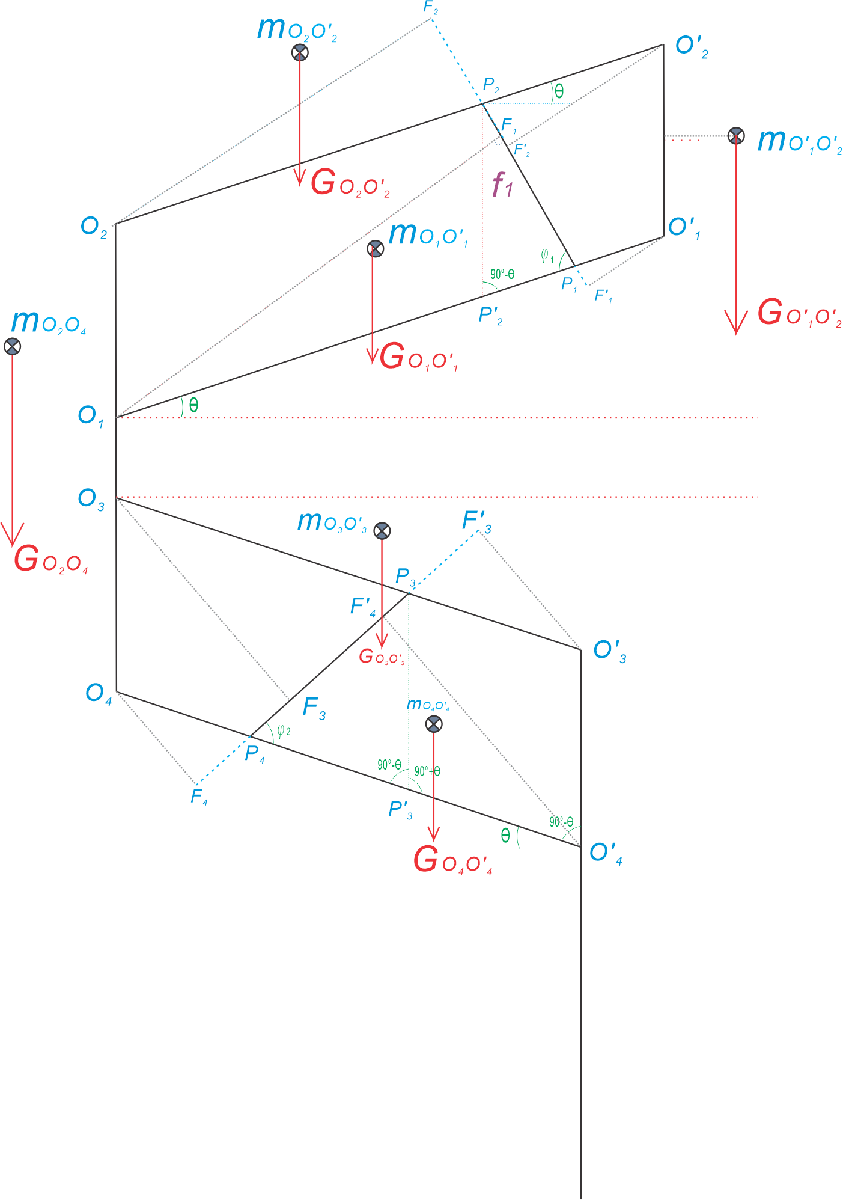

%theta=-45:1:45;  
thetad = -60:1:60;
phi=[];phi2=[];

g=9806.65; %in mm s^-2
%****************定義基礎結構尺寸及質量*********************** 。
LO1O_1=762 ;   %上部下連桿長度。
LO1O2=254;     %上部豎桿長度:後端介面。
LO3O_3=648;  %下部上連桿長度。
LO2O4=615;
LO1O3=615-2*254;      %兩齒輪間距

   
%*********
GO1O_1 = 0.84734661*g/1000; GO2O_2 = GO1O_1;
GO_1O_2 = 0.29870661*g/1000; 
GO3O_3 = 0.72422661*g/1000; GO4O_4 = GO3O_3;
GO2O4 = 0.67904403*g/1000;

%*************導出其他衍生結構*******************
LO2O_2=LO1O_1;    %上部上連桿長度=上部下連桿長度。
LO_1O_2=LO1O2;    %上區山桿 : 前端介面 =後端介面。

LO4O_4=LO3O_3;    %下部下連桿長度=下部上連桿長度。
LO3O4=LO1O2;    %下部豎桿支撐點長度=上部豎桿長度。
LO_3O_4=LO3O4;    %下部豎桿支撐點長度=上部豎桿長度。

以下為和彈性材料有關的參數

%******橡皮筋相關參量***********%
%i 為該彈性材料在組內的編號
%k1為彈性材料拉力係數 單位為N/mm
%li為彈性材料原長 單位為mm
%Di 為上下桿安裝點距離，即O1P1-O2P2
ki=[4 4 4];
li=[120 120 120];
Di= [200 60 -200];
%暫時忽略下部;


各桿件質心的數據︰$R$為質心和支點的距離、$\alpha$為質心和支點連線和桿件的夾角、$m$為質心(方向參考附圖)

RO1O_1= LO1O_1/2; alphaO1O_1d = 0; %alpha in degree
RO2O_2 = LO2O_2/2; alphaO2O_2d = 0;
RO3O_3 = LO3O_3/2; alphaO3O_3d= 0;
RO4O_4 = LO4O_4/2; alphaO4O_4d = 0;
RO_1O_2 = LO_1O_2/2; alphaO_1O_2d = 0;
RO2O4 = LO2O4/2 ; alphaO2O4d = 0;

將上述參數儲存至parameters.mat

save('parameters');